Question 1

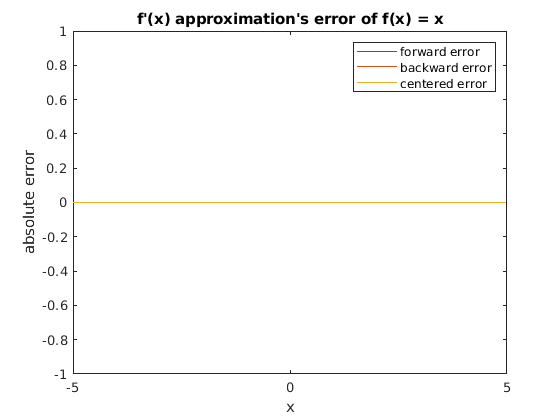

x = linspace(-5, 5, 100);

f = @(x) x;
fPrime = @(x) 1;
y = fPrime(x);
forwardFPrime = forward(f, x);
backwardFPrime = backward(f, x);
centeredFPrime = centered(f, x);
forwardError = abs(y - forwardFPrime);
backwardError = abs(y - backwardFPrime);
centeredError = abs(y - centeredFPrime);
plot(x, forwardError, x, backwardError, x, centeredError)
title("f'(x) approximation's error of f(x) = x")
legend("forward error", "backward error", "centered error")
ylabel("absolute error")
xlabel("x")

Accurate at all values because this graph is linear (polynomial power = 1)

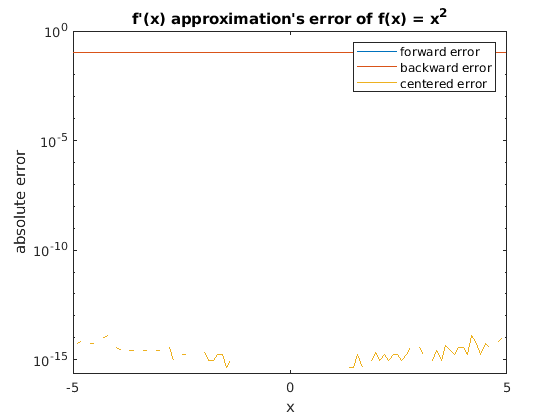

f = @(x) x.^2;
fPrime = @(x) 2.*x;
y = fPrime(x);
forwardFPrime = forward(f, x);
backwardFPrime = backward(f, x);
centeredFPrime = centered(f, x);
forwardError = abs(y - forwardFPrime);
backwardError = abs(y - backwardFPrime);
centeredError = abs(y - centeredFPrime);
semilogy(x, forwardError, x, backwardError, x, centeredError)
title("f'(x) approximation's error of f(x) = x^2")
legend("forward error", "backward error", "centered error")
ylabel("absolute error")
xlabel("x")

Centered seems to be VERY accurate for almost all values in this case, but the sparse lining of it are NONzero values where they are still very close to 0 (10^-15).

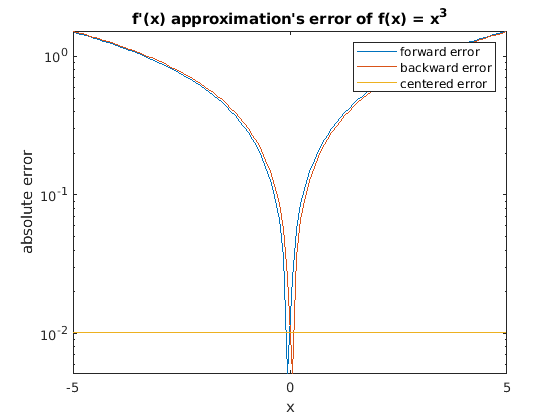

f = @(x) x.^3;
fPrime = @(x) 3.*x.^2;
y = fPrime(x);
forwardFPrime = forward(f, x);
backwardFPrime = backward(f, x);
centeredFPrime = centered(f, x);
forwardError = abs(y - forwardFPrime);
backwardError = abs(y - backwardFPrime);
centeredError = abs(y - centeredFPrime);
semilogy(x, forwardError, x, backwardError, x, centeredError)
title("f'(x) approximation's error of f(x) = x^3")
legend("forward error", "backward error", "centered error")
ylabel("absolute error")
xlabel("x")

For forward and backward, it is accurate at some value around -4 and 4 and centered is accurate at some value around -0.5 and 0.5.

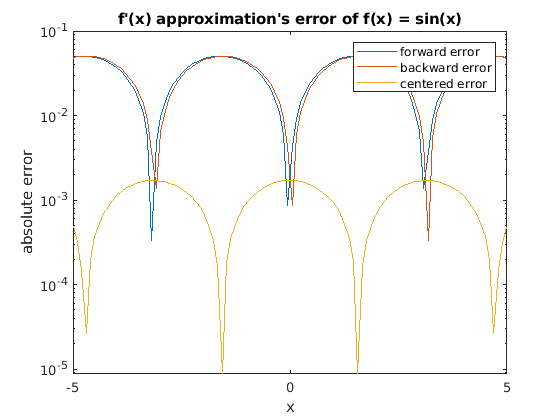

f = @(x) sin(x);
fPrime = @(x) cos(x);
y = fPrime(x);
forwardFPrime = forward(f, x);
backwardFPrime = backward(f, x);
centeredFPrime = centered(f, x);
forwardError = abs(y - forwardFPrime);
backwardError = abs(y - backwardFPrime);
centeredError = abs(y - centeredFPrime);
semilogy(x, forwardError, x, backwardError, x, centeredError)
title("f'(x) approximation's error of f(x) = sin(x)")
legend("forward error", "backward error", "centered error")
ylabel("absolute error")
xlabel("x")

Error tends to approach 0 at those troughs of each different function, so forward and backward will do it roughly around -3, 0, and 3. For centered, it does so as it approached -5, 5, 1.5, and -1.5.

Question 2

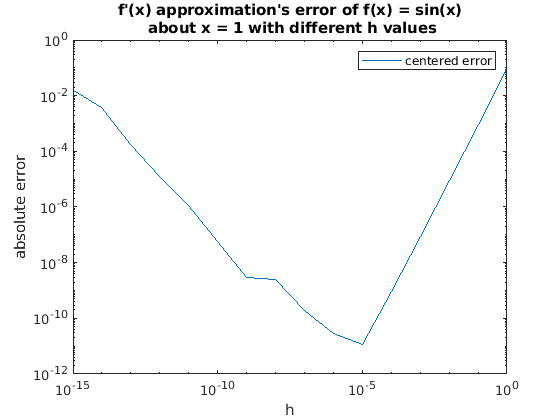

f = @(x) sin(x);
centeredApprox = @(h) (f(1 + h) - f(1 - h))/(2.*h);
x = [];
errors = [];
for i = 1:16;
    x(i) = 1/(10^(i - 1));
    errors(i) = abs(cos(1) - centeredApprox(x(i)));
end
loglog(x, errors);
title({"f'(x) approximation's error of f(x) = sin(x)", " about x = 1 with different h values"})
legend("centered error")
xlabel("h")
ylabel("absolute error")

Error stops decreasing at about 10^-5, which is semi-reasonable since it starts to get bugged by machine roundoff.

Question 3

X = [1,2,3,4,5];
f = @(x) 5.*x.^3 + 2.*x.^2 + x + 0;
y = num_diff(X,f(X),4.5,3)

y = 30.0000

function fPrime = forward(f, x)
    h = x(2) - x(1);
    fPrime = [];
    for i = 1:numel(x)
        fPrime(i) = (f(x(i) + h) - f(x(i)))/h;
    end
end

function fPrime = backward(f, x)
    h = x(2) - x(1);
    fPrime = [];
    for i = 1:numel(x)
        fPrime(i) = (f(x(i)) - f(x(i) - h))/h;
    end
end

function fPrime = centered(f, x)
    h = x(2) - x(1);
    fPrime = [];
    for i = 1:numel(x)
        fPrime(i) = (f(x(i) + h) - f(x(i) - h))/(2*h);
    end
end

function a = linterp_poly(X, Y)
a = zeros(1,numel(X));
for i = 1:numel(X)
aa = poly(X([1:i-1 i+1:end]));
a = a + Y(i) * aa / polyval(aa, X(i));
end
end

function y = num_diff(X, Y, x, d)
    vals = linterp_poly(X, Y);
    for i = 1:d
        vals = polyder(vals);
    end
    y = polyval(vals, x);
end